%% demo_ACC_loaded.mlx
clear; clc; close all;

%% ===================== Reproducibility note =====================
% This script evaluates four controllers under the same ACC closed-loop setup:
%
%   Opt:
%       The teacher QP controller. It is rebuilt here from the public ACC
%       model, hard interface, soft constraints, and objective.
%
%   Cert:
%       The proposed certified executor. The offline certified-library
%       construction, active-library completion, and training toolbox are
%       not included in this release. A prebuilt deployment object is loaded.
%
%   NN:
%       A pure neural-network baseline. For exact closed-loop reproduction,
%       this script uses the saved NNDeploy weights.
%
%   NN+Proj:
%       The same NN followed by a Euclidean projection onto
%       S*xi + G*u <= b whenever the NN output violates the hard interface.
%
% The released XTrain and YTrain are included for transparency and optional
% retraining of public baselines. The default closed-loop run does not retrain.

%% ===================== Initialization =====================
rng(3);

%% ===================== Load release package =====================
release_mat = 'demo_ACC_release_pack.mat';
load(release_mat, 'problem', 'qp_cfg', 'train_data', 'cert_info', 'nn_info', 'sim_cfg', 'plot_cfg', 'ctrl');

G         = problem.G;
S         = problem.S;
b         = problem.b;
Ts        = problem.Ts;
Ts_us     = problem.Ts_us;
eps_feas  = problem.eps_feas;
cd        = problem.cd;
tau       = problem.tau;
g         = problem.g;
umin      = problem.umin;
umax      = problem.umax;
Dmin      = problem.Dmin;
Dmax      = problem.Dmax;
vmin      = problem.vmin;
vmax      = problem.vmax;
vLmin     = problem.vLmin;
vLmax     = problem.vLmax;
vdes_min  = problem.vdes_min;
vdes_max  = problem.vdes_max;

OPCert    = ctrl.OPCert;
NNDeploy  = ctrl.NNDeploy;

OPCert.mex_ready = false;
OPCert.mex_id    = [];

nTest    = sim_cfg.nTest;
xi0      = sim_cfg.xi0;
eta0     = sim_cfg.eta0;
VdesTest = sim_cfg.VdesTest;
VLTest   = sim_cfg.VLTest;
name     = sim_cfg.name;
nMethod  = sim_cfg.nMethod;

maxNumCompThreads(sim_cfg.maxNumCompThreads);

fprintf(['\n==================== ACC LOADED DEMO ====================\n' ...
         '[Load] %s\n' ...
         '[Data] XTrain = %d-by-%d, YTrain = %d-by-%d\n' ...
         '[Cert] nLaw = %d, nAct = %d, cover = %s\n' ...
         '[NN] train_mse_scaled = %.3e, train_mse_raw = %.3e\n'], ...
         release_mat, ...
         size(train_data.XTrain, 1), size(train_data.XTrain, 2), ...
         size(train_data.YTrain, 1), size(train_data.YTrain, 2), ...
         cert_info.nLaw, cert_info.nAct, cert_info.cover_status, ...
         nn_info.nn_train_mse_scaled, nn_info.nn_train_mse_raw);


==================== ACC LOADED DEMO ====================
[Load] demo_ACC_release_pack.mat
[Data] XTrain = 4-by-20000, YTrain = 1-by-20000
[Cert] nLaw = 5, nAct = 4, cover = certified
[NN] train_mse_scaled = 1.760e-03, train_mse_raw = 3.429e-02



%% ===================== Rebuild public Opt baseline =====================
ops = sdpsettings('solver', qp_cfg.solver, 'verbose', 0);

xi    = sdpvar(3, 1);
vdes  = sdpvar(1, 1);
u     = sdpvar(1, 1);
del   = sdpvar(1, 1);
kappa = sdpvar(1, 1);
s0    = sdpvar(1, 1);

[D, v, vL] = deal(xi(1), xi(2), xi(3));

D1  = D + Ts * (vL - v);
v1  = (1 - Ts * cd) * v + Ts * u;
hk  = D - tau * v;
hk1 = D1 - tau * v1;
Vk  = (v - vdes)^2;
Vk1 = (v1 - vdes)^2;

C = [
    umin <= u
    u <= umax
    vmin <= v1
    v1 <= vmax
    del >= 0
    0 <= kappa
    kappa <= 1
    s0 >= 0
    s0 <= qp_cfg.s0_ref
    hk1 >= 0
    hk1 >= (1 - kappa) * hk + qp_cfg.s0_ref
    Vk1 - Vk <= -qp_cfg.alphaV * Vk + del
];

u_ref = 0.8 * (vdes - v) + cd * v;

J = qp_cfg.w_u * (u - u_ref)^2 ...
    + qp_cfg.w_del * del ...
    + qp_cfg.w_kappa * (kappa - 0.8)^2 ...
    + qp_cfg.w_s0 * (s0 - qp_cfg.s0_ref)^2;

OPbase_acc = optimizer(C, J, ops, {xi, vdes}, u);

%% ===================== Rebuild public NN+Proj baseline =====================
xi_proj    = sdpvar(3, 1);
u_nn_proj  = sdpvar(1, 1);
u_proj     = sdpvar(1, 1);

Cproj      = S * xi_proj + G * u_proj <= b;
Jproj      = (u_proj - u_nn_proj)^2;
OPproj_acc = optimizer(Cproj, Jproj, ops, {xi_proj, u_nn_proj}, u_proj);

%% ===================== Initialize deployed NN and warm-up =====================
nn_policy_mex('clear');
nn_policy_mex('init', NNDeploy);

u0_opt  = OPbase_acc{xi0, eta0};
u0_cert = OPCert.cert_forward(xi0, eta0);
u0_nn   = nn_policy_mex('eval', [xi0; eta0]);
u0_proj = OPproj_acc{xi0, double(u0_nn)};

v0_opt  = max([0; S * xi0 + G * double(u0_opt) - b]);
v0_cert = max([0; S * xi0 + G * double(u0_cert) - b]);
v0_nn   = max([0; S * xi0 + G * double(u0_nn) - b]);
v0_proj = max([0; S * xi0 + G * double(u0_proj) - b]);

fprintf(['[Warm-up] Opt     u0 = %.6f, max_violation = %.3e\n' ...
         '[Warm-up] Cert    u0 = %.6f, max_violation = %.3e\n' ...
         '[Warm-up] NN      u0 = %.6f, max_violation = %.3e\n' ...
         '[Warm-up] NN+Proj u0 = %.6f, max_violation = %.3e\n'], ...
         double(u0_opt), v0_opt, double(u0_cert), v0_cert, ...
         double(u0_nn), v0_nn, double(u0_proj), v0_proj);

[Warm-up] Opt     u0 = 2.943000, max_violation = 0.000e+00
[Warm-up] Cert    u0 = 2.909931, max_violation = 0.000e+00
[Warm-up] NN      u0 = 2.840510, max_violation = 0.000e+00
[Warm-up] NN+Proj u0 = 2.840510, max_violation = 0.000e+00


%% ===================== Closed-loop test =====================
time_us      = nan(nTest, nMethod);
u_traj       = nan(nTest, nMethod);
viol_traj    = nan(nTest, nMethod);
hviol_traj   = nan(nTest, nMethod);
track_traj   = nan(nTest, nMethod);
xi_traj      = nan(nTest + 1, 3, nMethod);
proj_trigger = false(nTest, 1);
proj_fail    = false(nTest, 1);
alive_method = true(1, nMethod);
fail_step    = nan(1, nMethod);

for j = 1:nMethod
    xi_traj(1, :, j) = xi0.';
end

xi_now = repmat(xi0, 1, nMethod);

for k = 1:nTest
    vLk   = VLTest(k);
    vdesk = VdesTest(k);

    for j = 1:nMethod
        if ~alive_method(j)
            xi_traj(k + 1, :, j) = nan(1, 3);
            continue;
        end

        xik    = xi_now(:, j);
        xik(3) = vLk;

        t0 = tic;

        if j == 1
            uk = double(OPbase_acc{xik, vdesk});

        elseif j == 2
            uk = double(OPCert.cert_forward(xik, vdesk));

        elseif j == 3
            uk = double(nn_policy_mex('eval', [xik; vdesk]));

        else
            uk0             = double(nn_policy_mex('eval', [xik; vdesk]));
            proj_hit        = max([0; S * xik + G * uk0 - b]) > eps_feas;
            proj_trigger(k) = proj_hit;

            if proj_hit
                [uk_tmp, proj_problem] = OPproj_acc{xik, uk0};
                uk = double(uk_tmp);

                if proj_problem ~= 0 || isempty(uk) || any(~isfinite(uk))
                    time_us(k, j)     = 1e6 * toc(t0);
                    proj_fail(k)      = true;
                    alive_method(j)   = false;
                    fail_step(j)      = k;
                    viol_traj(k, j)   = inf;
                    hviol_traj(k, j)  = inf;
                    track_traj(k, j)  = inf;
                    u_traj(k, j)      = nan;
                    xi_traj(k + 1:end, :, j) = nan;
                    continue;
                end
            else
                uk = uk0;
            end
        end

        if isempty(uk) || any(~isfinite(uk))
            time_us(k, j)     = 1e6 * toc(t0);
            alive_method(j)   = false;
            fail_step(j)      = k;
            viol_traj(k, j)   = inf;
            hviol_traj(k, j)  = inf;
            track_traj(k, j)  = inf;
            u_traj(k, j)      = nan;
            xi_traj(k + 1:end, :, j) = nan;
            continue;
        end

        time_us(k, j) = 1e6 * toc(t0);

        [D, v, vL] = deal(xik(1), xik(2), xik(3));

        D1      = D + Ts * (vL - v);
        v1      = (1 - Ts * cd) * v + Ts * uk;
        xi_next = [D1; v1; vL];

        viol_traj(k, j)  = max([0; S * xik + G * uk - b]);
        hviol_traj(k, j) = max(0, -(D1 - tau * v1));
        track_traj(k, j) = (v1 - vdesk)^2 + 1e-2 * (uk - (0.8 * (vdesk - v) + cd * v))^2;

        u_traj(k, j)         = uk;
        xi_traj(k + 1, :, j) = xi_next.';
        xi_now(:, j)         = xi_next;
    end
end

%% ===================== Report =====================
tOpt_mean  = mean(time_us(:, 1), 'omitnan');
proj_rate  = mean(proj_trigger, 'omitnan');
pfail_rate = mean(proj_fail, 'omitnan');

fprintf(['\n==================== ACC LOADED REPORT ====================\n' ...
         'Ts = %.0fus, nTest = %d, eps_feas = %.1e\n' ...
         'timing-only protocol: runtime is measured but not injected into the state update\n' ...
         'NN+Proj projection rate = %.2f%%, projection-failure rate = %.2f%%\n' ...
         '-------------------------------------------------------------------------------------------------------\n' ...
         '%-9s | %-22s | %-8s | %-9s | %-8s | %-12s | %-10s\n' ...
         '-------------------------------------------------------------------------------------------------------\n'], ...
         Ts_us, nTest, eps_feas, 100 * proj_rate, 100 * pfail_rate, ...
         'Method', 'time_us mean/p50/p99', 'speedup', 'max viol.', 'viol.', 'safe?', 'cost');


==================== ACC LOADED REPORT ====================
Ts = 20000us, nTest = 1500, eps_feas = 1.0e-04
timing-only protocol: runtime is measured but not injected into the state update
NN+Proj projection rate = 7.93%, projection-failure rate = 0.07%
-------------------------------------------------------------------------------------------------------
Method    | time_us mean/p50/p99   | speedup  | max viol. | viol.    | safe?        | cost      
-------------------------------------------------------------------------------------------------------



for j = 1:nMethod
    tj          = time_us(:, j);
    tj_finite   = tj(isfinite(tj));
    t_mean      = mean(tj, 'omitnan');
    t_p50       = prctile(tj_finite, 50);
    t_p99       = prctile(tj_finite, 99);
    speedup_opt = tOpt_mean / max(t_mean, eps);

    vj          = viol_traj(:, j);
    max_viol    = max(vj, [], 'omitnan');
    viol_rate   = mean(vj > eps_feas, 'omitnan');

    bad_h       = find(hviol_traj(:, j) > eps_feas, 1, 'first');
    bad_f       = fail_step(j);

    if isempty(bad_h) && isnan(bad_f)
        safe_str = 'yes';
    else
        bad_all = [bad_h, bad_f];
        bad_all = bad_all(isfinite(bad_all));
        safe_str = sprintf('no(k=%d)', min(bad_all));
    end

    if strcmp(safe_str, 'yes') && all(isfinite(track_traj(:, j)))
        cost_str = sprintf('%.3e', mean(track_traj(:, j), 'omitnan'));
    else
        cost_str = 'fail';
    end

    fprintf('%-9s | %7.1f/%6.1f/%6.1f | %7.2fx | %9.2e | %6.2f%% | %-12s | %10s\n', ...
        name{j}, t_mean, t_p50, t_p99, speedup_opt, max_viol, 100 * viol_rate, safe_str, cost_str);
end

Opt       |   805.0/ 783.0/1286.0 |    1.00x |  1.54e-08 |   0.00% | yes          |  1.648e+01
Cert      |    24.7/  21.7/  56.3 |   32.60x |  0.00e+00 |   0.00% | yes          |  1.651e+01
NN        |     8.9/   7.9/  21.2 |   90.29x |  2.14e+02 |  70.00% | no(k=472)    |       fail
NN+Proj   |   173.8/   6.4/1054.4 |    4.63x |       Inf |   0.07% | no(k=568)    |       fail



fprintf(['-------------------------------------------------------------------------------------------------------\n' ...
         'safe? = yes only if no step satisfies h_{k+1} < -eps_feas and no rollout/projection failure occurs.\n' ...
         'cost is the mean closed-loop stage cost and is reported only for safe finite rollouts.\n']);

-------------------------------------------------------------------------------------------------------
safe? = yes only if no step satisfies h_{k+1} < -eps_feas and no rollout/projection failure occurs.
cost is the mean closed-loop stage cost and is reported only for safe finite rollouts.



for j = 1:nMethod
    if ~isnan(fail_step(j))
        fprintf('[Fail] %s stopped at k = %d\n', name{j}, fail_step(j));
    end
end

[Fail] NN+Proj stopped at k = 568


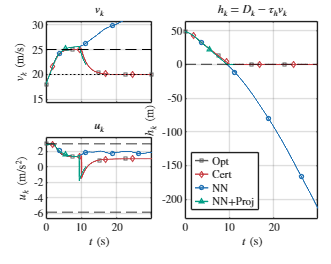


%% ===================== Plot =====================
t_state = (0:nTest) * Ts;
t_step  = (0:nTest - 1) * Ts;
h_traj  = squeeze(xi_traj(1:end-1, 1, :) - tau * xi_traj(1:end-1, 2, :));

fig_w_in = plot_cfg.fig_w_in;
fig_h_in = plot_cfg.fig_h_in;
fs       = plot_cfg.fs;
lw       = plot_cfg.lw;
lw_ref   = plot_cfg.lw_ref;
ms       = plot_cfg.ms;
clr      = plot_cfg.clr;
mk       = plot_cfg.mk;

mk_step     = max(1, round(nTest / 4));
mk_id_step  = 1:mk_step:nTest;
mk_id_state = 1:mk_step:(nTest + 1);
mk_shift    = round(linspace(0, 0.75 * mk_step, nMethod));

v_margin = 0.05 * max(1, vmax - vmin);
u_margin = 0.10 * max(1, umax - umin);
h_min    = min(h_traj, [], 'all');
h_max    = max(h_traj, [], 'all');
h_margin = 0.06 * max(1, h_max - h_min);

fig = figure('Color', 'w');
set(fig, 'Units', 'inches', 'Position', [1, 1, fig_w_in, fig_h_in], ...
    'PaperUnits', 'inches', 'PaperPosition', [0, 0, fig_w_in, fig_h_in], ...
    'PaperSize', [fig_w_in, fig_h_in], 'Renderer', 'painters');

posV = [0.14, 0.61, 0.32, 0.31];
posU = [0.14, 0.17, 0.32, 0.31];
posH = [0.56, 0.17, 0.40, 0.75];

axV = axes('Position', posV);
hold(axV, 'on'); grid(axV, 'on');

for j = 1:nMethod
    hp = plot(axV, t_state, xi_traj(:, 2, j), 'LineWidth', lw, ...
        'Color', clr(j, :), 'Marker', mk{j}, 'MarkerSize', ms, ...
        'MarkerFaceColor', 'none', 'MarkerEdgeColor', clr(j, :), ...
        'HandleVisibility', 'off');

    id = mk_id_state + mk_shift(j);
    hp.MarkerIndices = id(id <= nTest + 1);
end

plot(axV, t_step, VdesTest, 'k--', 'LineWidth', lw_ref, 'HandleVisibility', 'off');
plot(axV, t_step, VLTest, 'k:', 'LineWidth', lw_ref, 'HandleVisibility', 'off');

xlim(axV, [t_state(1), t_state(end)]);
ylim(axV, [vmin - v_margin, vmax + v_margin]);
ylabel(axV, '$v_k\;(\mathrm{m/s})$', 'Interpreter', 'latex');
title(axV, '$v_k$', 'Interpreter', 'latex');
set(axV, 'XTickLabel', []);

axU = axes('Position', posU);
hold(axU, 'on'); grid(axU, 'on');

for j = 1:nMethod
    hp = plot(axU, t_step, u_traj(:, j), 'LineWidth', lw, ...
        'Color', clr(j, :), 'Marker', mk{j}, 'MarkerSize', ms, ...
        'MarkerFaceColor', 'none', 'MarkerEdgeColor', clr(j, :), ...
        'HandleVisibility', 'off');

    id = mk_id_step + mk_shift(j);
    hp.MarkerIndices = id(id <= nTest);
end

yline(axU, umin, 'k--', 'LineWidth', lw_ref, 'HandleVisibility', 'off');
yline(axU, umax, 'k--', 'LineWidth', lw_ref, 'HandleVisibility', 'off');

xlim(axU, [t_step(1), t_step(end)]);
ylim(axU, [umin - u_margin, umax + u_margin]);
xlabel(axU, '$t\;(\mathrm{s})$', 'Interpreter', 'latex');
ylabel(axU, '$u_k\;(\mathrm{m/s^2})$', 'Interpreter', 'latex');
title(axU, '$u_k$', 'Interpreter', 'latex');

axH = axes('Position', posH);
hold(axH, 'on'); grid(axH, 'on');

h_leg = gobjects(nMethod, 1);

for j = 1:nMethod
    h_leg(j) = plot(axH, t_step, h_traj(:, j), 'LineWidth', lw, ...
        'Color', clr(j, :), 'Marker', mk{j}, 'MarkerSize', ms, ...
        'MarkerFaceColor', 'none', 'MarkerEdgeColor', clr(j, :));

    id = mk_id_step + mk_shift(j);
    h_leg(j).MarkerIndices = id(id <= nTest);
end

yline(axH, 0, 'k--', 'LineWidth', lw_ref, 'HandleVisibility', 'off');

xlim(axH, [t_step(1), t_step(end)]);
ylim(axH, [min(0, h_min) - h_margin, h_max + h_margin]);
xlabel(axH, '$t\;(\mathrm{s})$', 'Interpreter', 'latex');
ylabel(axH, '$h_k\;(\mathrm{m})$', 'Interpreter', 'latex');
title(axH, '$h_k=D_k-\tau_h v_k$', 'Interpreter', 'latex');

lgd = legend(axH, h_leg, name, 'Interpreter', 'latex', 'Location', 'southwest', 'Box', 'on');
set(lgd, 'FontSize', fs, 'LineWidth', 0.5);
try, lgd.ItemTokenSize = [10, 7]; catch, end

set([axV, axU, axH], ...
    'FontSize', fs, ...
    'TickLabelInterpreter', 'latex', ...
    'LineWidth', 0.7, ...
    'Box', 'on');

%% ===================== Export fig =====================
pdf_name = 'sim_ACC.pdf';

set(fig, 'Renderer', 'painters');
set(fig, 'PaperUnits', 'inches');
set(fig, 'PaperPosition', [0, 0, fig_w_in, fig_h_in]);
set(fig, 'PaperSize', [fig_w_in, fig_h_in]);

exportgraphics(fig, pdf_name, 'ContentType', 'vector');

% exportgraphics(fig, 'sim_ACC.png');

fprintf('[Plot] saved PDF: %s\n', pdf_name);

[Plot] saved PDF: sim_ACC.pdf
